07222113d邓俊烽

测试各种程序对于高阶矩阵的效果

第一章测试200阶的各种分解

clear;clc;
N=200;
A=1+randn(N,N)*10;
textEig=1+randn(N,1)*10;
b=A*textEig;
method={'LUGauss','FullLUGauss','ColLUGauss','Cholesky','ImprovedCholesky'}

method = 1×5 cell 数组
    {'LUGauss'}    {'FullLUGauss'}    {'ColLUGauss'}    {'Cholesky'}    {'ImprovedCholesky'}


for i=1:length(method)
    M=method{i};
    disp(['method: ',M]);
    textEig=SolLinearEqu(A,b,M);
    disp('norm(x-exactx):');
    disp(norm(textEig-textEig));
    disp('----------');
end

method: LUGauss


L =      1.000000000000000e+00                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0        

U =      2.218561765807975e+00     1.940762786625202e+00     3.983302289205736e+00     2.272699206181013e+00     1.014993080306718e+01     1.364305555244916e+01    -1.970904692239808e+00     9.290944145823348e+00    -1.012883031245323e+01    -5.195435461049758e+00    -3.683252439405818e+00     2.341187802120952e+01     1.152872188105172e+01     8.243686092667529e+00    -1.604501592752416e+01     1.042546502254907e+01     1.253499889034005e+01    -4.744513221192026e+00     2.112986911072213e+01     1.110319688734138e+01     1.634498811633429e+01     2.350090897617454e+01    -2.668602825628619e+00    -9.738628413773036e+00    -4.417418328120157e+00    -5.031070390780027e+00     4.686962226723864e+00     6.139836889698927e+00    -1.389254889844574e+00    -1.368118126427947e+01     1.367329452607562e+01    -2.738752955968295e-01     3.186691862145073e+01    -2.763961781742546e+00     7.984084713133977e+00     4.312307891259888e-01    -3.214105434125848e+00    -3.703986874316753e+00     5.0

norm(x-exactx):


     0



----------


method: FullLUGauss


norm(x-exactx):


     0



----------


method: ColLUGauss


L =      1.000000000000000e+00                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0        

U =      2.500984196460164e+01     4.964404572498320e+00    -5.522068815565166e+00     3.264441938110466e+00     8.174094835694683e-01     1.824968287793268e+00    -1.510184712941362e+01     5.654756567779309e+00    -1.502876299489713e+00     5.358208711458660e+00    -1.203052743665538e+00    -1.651123431149795e+01     5.133479482994193e+00     1.458467820944957e+00    -7.688949535560422e+00     1.616896967760301e+00    -4.920717432532333e+00     1.909362947311925e+00     2.387490311587959e+01     4.890104496662795e+00    -3.885977385609555e+00     7.132119698278102e+00     1.038817539335418e+00    -1.761174912907774e+01    -4.379102370196550e+00    -4.359596366916164e+00    -6.026992233238317e+00    -1.268988031844540e-01     6.628296419886847e+00     3.811632842834947e+01     4.333791315504143e+00    -1.843398568183155e+01     1.484068566782083e+01    -1.255544250115366e+01    -1.071235937973796e+01     1.213685386058971e+01     1.659046839389512e+00     7.604250266196332e+00    -2.4

P =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

norm(x-exactx):


     0



----------


method: Cholesky


A ~= A',不能进行Cholsky分解


norm(x-exactx):


   NaN



----------


method: ImprovedCholesky


A ~= A',不能进行Cholsky分解


norm(x-exactx):


   NaN



----------


[Q,R]=QRDec(A)

Q =      1.555800414631958e-02     1.428858836570766e-02     2.687151826375666e-02     1.681851559919765e-02     7.086529356893791e-02     1.001804181389370e-01    -1.579383891857678e-02     6.458497905854654e-02    -7.171895101727283e-02    -2.071357350594382e-02    -2.421960966866803e-02     1.456342105747307e-01     7.533364574458987e-02     6.287094313900120e-02    -1.241139189709186e-01     6.823059708788530e-02     5.755169682443927e-02    -3.240819153082544e-02     1.104607256306253e-01     9.460359852146943e-02     1.725285156332020e-01     1.475838919616831e-01    -2.139059273455660e-02    -1.140731894300958e-01    -2.875122621901182e-02    -3.441424048893667e-02     3.907743394548813e-02     1.047226527117985e-02    -8.776638500835350e-03    -9.253126119577812e-02     5.499840182139973e-02     2.988387804278486e-02     1.944679869659629e-01     1.157399213881934e-02     3.510345479341128e-02    -3.608737315755177e-02    -8.086658817639602e-03    -3.374345076571579e-02     1.5

R =      1.425993813179948e+02     6.095397390047480e-01     1.529366436756482e+01    -4.111237179015025e-01     1.430127634207056e+01     1.381283999744165e+00     6.532640789025326e+00     1.132442692231130e+00     6.721668559182326e+00     1.248602359842863e+01     1.087965785329321e+01    -2.101183628128990e+01    -6.724449411339064e+00     9.579694098817889e+00     5.174810896561486e-01     5.117677863658178e-01    -7.401452098198144e+00    -3.904067546825468e+00    -1.650259714385734e+01    -2.062820379601262e+00    -1.159857687531485e+00     1.383070793781462e+01     1.824607395000042e+00     6.055608793626178e+00     7.122366166039166e+00    -1.024861917602900e+01    -1.602050659636813e+00     5.401943610180666e+00    -1.649306646990790e+01     2.525861376068329e+00     6.483936775959171e+00     8.097549546291644e+00     4.267879652315384e+00     4.582719821229788e+00    -1.417908952102583e+01    -3.475914128334519e+00     2.440165849488936e+01     1.534658905296191e+01    -1.9

[m,n]=size(A);
disp(norm(Q*[R;zeros(m-n,n)]-A));

     1.604260782595989e-12



CH4.测试五百阶的各种迭代

clear;clc;
N=500;
A = diag(20+randn(N,1),0) + diag(2+randn(N-1,1),1) + diag(2+randn(N-1,1),-1);
A=(A'*A)/2

A =      2.011707457908092e+02     4.558262611174864e+01     5.749187942402585e-01                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0        

exactx=randn(N,1)*10;
b=A*exactx;
disp('Jacobi迭代');

Jacobi迭代


	y = JacobiIterate(A,b);

迭代次数为60
迭代时间为0.0087985s


	disp('norm(y-exactx):');

norm(y-exactx):


	disp(norm(y-exactx));

     3.852905864869351e-14



    disp('norm(b-Ay)');

norm(b-Ay)


    disp(norm(b-A*y));

     7.440889733932907e-12




	disp('GS迭代');

GS迭代


	y = GSIterate(A,b);

迭代次数为28
运算时间为 0.0064857s


	disp('norm(y-exactx):');

norm(y-exactx):


	disp(norm(y-exactx));

     3.801533234264753e-14



     disp('norm(b-Ay)');

norm(b-Ay)


    disp(norm(b-A*y));

     7.033379868946508e-12




	disp('SOR迭代');

SOR迭代


	y = SORIterate(A,b,0.5);

迭代次数为94
迭代时间为0.010651s


	disp('norm2(y-exactx):');

norm2(y-exactx):


	disp(norm(y-exactx));

     1.240583697046834e-13



     disp('norm(b-Ay)');

norm(b-Ay)


    disp(norm(b-A*y));

     1.466422713242616e-11



    disp('-----------');

-----------


CH4测试1000阶的共轭梯度法的效果

clear;clc
n = 1000; % 矩阵大小
density = 0.1; % 稀疏矩阵的密度
A = sprandsym(n, density); % 生成稀疏对称随机矩阵
A = A + n * speye(n); % 确保矩阵正定（添加对角线元素）

% 验证矩阵正定性
try
    chol(A);
    disp('矩阵是正定的');
catch
    disp('矩阵不是正定的');
end

矩阵是正定的


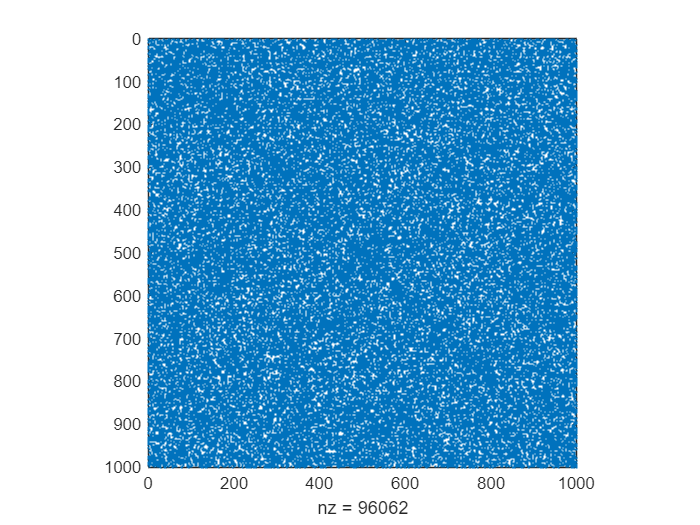


% 显示稀疏矩阵
spy(A); % 可视化稀疏矩阵的非零元素

disp(A); % 显示稀疏矩阵

   (1,1)        1.000000000000000e+03
   (8,1)       -2.886443299756543e-01
   (9,1)        1.220979495695306e-01
  (17,1)       -1.353431928641213e+00
  (47,1)       -7.805118557216717e-01
  (50,1)        3.281599161534265e-01
  (56,1)        4.715112433814170e-01
  (62,1)       -1.270231290489021e+00
  (69,1)        6.460396041221098e-02
 (107,1)       -7.332560673446117e-01
 (109,1)        1.109519985606244e+00
 (119,1)       -7.250555802726411e-03
 (131,1)        1.285666516179760e+00
 (143,1)       -6.912038648079132e-01
 (159,1)        1.289696050016488e+00
 (165,1)        3.234055621604767e-01
 (170,1)        4.234324132693075e-01
 (191,1)       -1.170246079853872e+00
 (210,1)       -1.934756027256086e+00
 (212,1)       -1.325580717894949e+00
 (217,1)       -2.912077220272432e-01
 (230,1)        2.520499439760512e+00
 (235,1)        2.200864151312264e-01
 (247,1)        1.547366515872692e+00
 (256,1)        3.157018688498153e-01
 (262,1)       -9.068336168889171e-01
 (296,1)    

exactx=10+randn(n,1)

exactx =      9.572933836668517e+00
     9.587392722793327e+00
     8.835056141246744e+00
     1.008023750048204e+01
     8.936035692474348e+00
     8.806128093616074e+00
     9.191781913490303e+00
     1.051001444835750e+01
     9.357543728101163e+00
     1.083617336094692e+01


b=A*exactx;
disp('实用的共轭梯度法');

实用的共轭梯度法


x=ConGradMethod(A,b);

迭代次数为16
迭代时间为0.0031442s


disp('norm(x-exactx)');

norm(x-exactx)


disp(norm(x-exactx));

     1.779839525658433e-13



disp('norm(b-Ax)');

norm(b-Ax)


    disp(norm(b-A*x));

     1.770293531248328e-10



disp('预优的共轭梯度法');

预优的共轭梯度法


x=PreConGradMethod(A,b);

迭代次数为23
迭代时间为 0.0069553s


disp('norm(x-exactx)');

norm(x-exactx)


disp(norm(x-exactx));

     1.739401687303475e-13



disp('norm(b-Ax)');

norm(b-Ax)


    disp(norm(b-A*x));

     1.728518548509550e-10



CH05

clear;clc
N=200;
A=10+randn(N,N);
format longE
[Q,H]=HessenbergDec(A)

Q =      1.000000000000000e+00                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0        

H =      1.045519741816818e+01     1.396716372333637e+02     1.269880458526571e+01    -8.504493444792944e-01     7.232999132760798e-02    -4.128932800364747e-01     8.132506312518565e-01    -4.595593820684298e-01     2.529130043929711e+00    -2.633290391024912e-01     2.053370549014392e+00    -4.111778112845031e-01     4.065997711656358e-01     8.223692836932694e-01    -1.901890845272496e+00    -1.690212749969243e-02     1.226808953052039e+00     1.366922037727496e+00    -1.572733679330072e+00    -1.542180278963010e-02    -2.682137682970877e-01     3.378256618522836e-01     1.421484536274342e+00     1.216703032319550e+00     1.894173801720623e+00     3.534521484733857e-01     1.571815966312468e-01     2.191573741172698e+00    -4.190879726569824e-01     9.740159530612834e-02     8.851732169483906e-01     1.613638079777851e+00     1.363046445239258e+00    -1.260183259822070e+00    -1.303784640552398e-01    -6.367200559821509e-01     1.029293653814688e+00    -3.540843177059010e-02     1.1

第六章

clear;clc;
N=200;
A=randi([1,10],N,N);
A=(A'+A)/2;

%测试
textEig = sort(eig(A));
% 找到绝对值最大的特征值
[~, idx1] = max(abs(textEig)); % 找到绝对值最大的索引
[~, idx2] = min(abs(textEig)); % 找到绝对值最大的索引
maxeig = textEig(idx1)% 获取对应的原值

maxeig =      1.093067436525264e+03


mineig = textEig(idx2)

mineig =     -1.858590999487910e-01


%自己的代码

eig1=PowerMethod(A)

迭代次数为10
迭代时间为0.0004949s


eig1 =      1.093067436525280e+03


eig2=InversePowerMethod(A)

eig2 =     -1.858590999488015e-01



%双重步迭代
[~,Hess1] = HessenbergDec(A);
[P,Hess2] = DoubleStepQR(Hess1);
disp("norm(P'*Hess1*P-Hess2)");

norm(P'*Hess1*P-Hess2)


disp(norm(P'*Hess1*P-Hess2));

     9.188490590627478e-14



测试300阶的特征值和特征向量

clear;clc;
N=300;
A=rand(N,N);
[~,~,Eig]=ImpQR(A)

迭代次数为: 544
迭代时间为40.1288s


Eig =       1.696710924823867e-01 + 0.000000000000000e+00i
     -2.286664250031897e-01 + 0.000000000000000e+00i
      6.544671023244275e-02 - 4.385750812741284e-01i
      6.544671023244275e-02 + 4.385750812741284e-01i
      6.313523245776334e-01 + 0.000000000000000e+00i
     -6.502442169569299e-01 - 1.247967459216381e-01i
     -6.502442169569299e-01 + 1.247967459216381e-01i
      6.714982947816353e-01 - 4.615345041911232e-01i
      6.714982947816353e-01 + 4.615345041911232e-01i
      1.610450156127103e-01 - 8.221701187362636e-01i


textEig=sort(eig(A))

textEig =       1.696710924824935e-01 + 0.000000000000000e+00i
     -2.286664250031627e-01 + 0.000000000000000e+00i
      6.544671023238663e-02 - 4.385750812741377e-01i
      6.544671023238663e-02 + 4.385750812741377e-01i
      6.313523245776146e-01 + 0.000000000000000e+00i
     -6.502442169569556e-01 - 1.247967459216410e-01i
     -6.502442169569556e-01 + 1.247967459216410e-01i
      6.714982947816378e-01 - 4.615345041911241e-01i
      6.714982947816378e-01 + 4.615345041911241e-01i
      1.610450156127187e-01 - 8.221701187362335e-01i


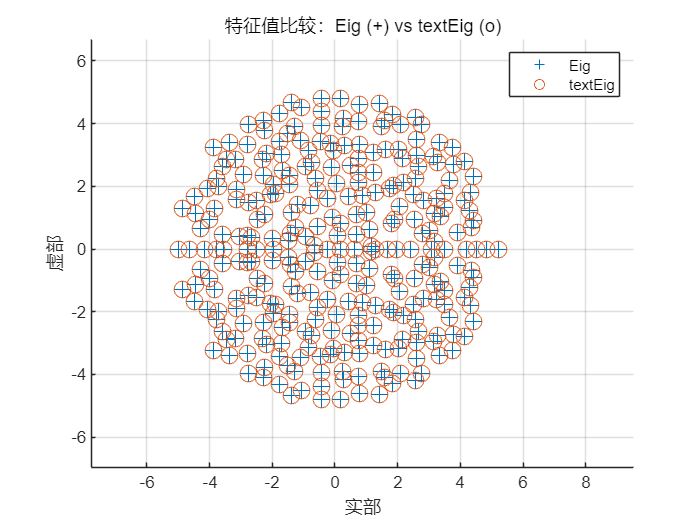

% 绘制实部和虚部
figure;
hold on;
% 绘制 Eig，用 + 表示
scatter(real(Eig), imag(Eig), 100, '+'); % 红色 + 表示 Eig
% 绘制 textEig，用 o 表示
scatter(real(textEig), imag(textEig), 100, 'o'); % 蓝色 o 表示 textEig
% 图形设置
xlabel('实部');
ylabel('虚部');
title('特征值比较：Eig (+) vs textEig (o)');
legend('Eig', 'textEig');
grid on;
axis equal; % 保持横纵轴比例一致
hold off;

[Eig,Vector]=FindEig(A);

迭代次数为: 544
迭代时间为39.9169s


disp(norm(A*Vector-Vector*diag(Eig)));

     3.292009332448483e-12

